## Main

% 清理
clear
clc

## 1. 优化问题与Matlab中的非线性优化函数

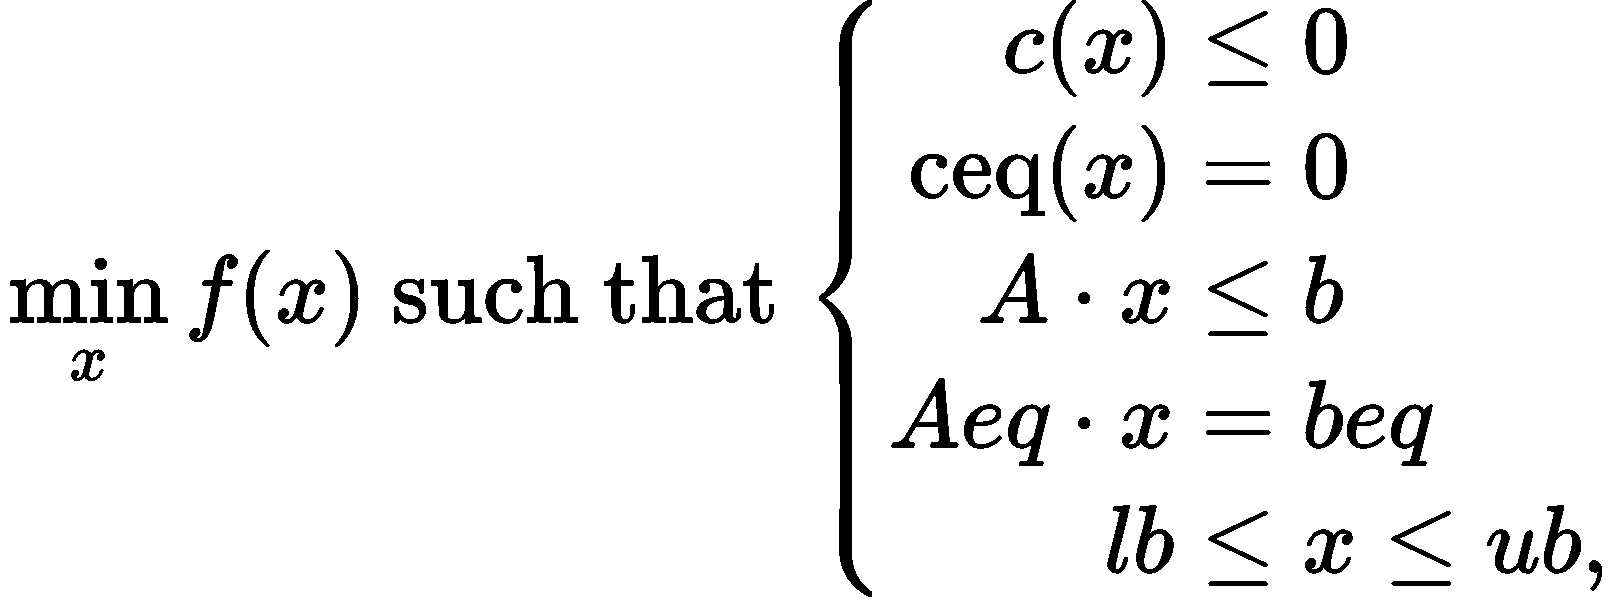

其中$b$和$\textrm{beq}$是向量，$A$和$\textrm{Aeq}$是矩阵，$c\left(x\right)$和$\textrm{ceq}\left(x\right)$是返回值为向量的函数，$f\left(x\right)$是返回值为标量的函数。$f\left(x\right),c\left(x\right)$和$\textrm{ceq}\left(x\right)$都是非线性函数。

$x$, $\textrm{Lb}$和$\textrm{ub}$都可以作为向量和矩阵进行传递。

#### Matlab中，非线性优化函数的调用：

`[x, fval] = fmincon(fun, x0, A, b, Aeq, beq, lb, ub, nonlcon, options)`

`其中：`

- `x：优化后的最值点`

- `fval：最优值`

- `fun：目标函数的句柄，例如fun = @(x)100*(x(2)-x(1)^2)^2 + (1-x(1))^2或fun = @myfun`

- `nonlcon：非线性约束(Nonlinear constraint)`

- `options：待定的优化算法`

## 2.目标函数的设定

### 2.1 目标函数的公式

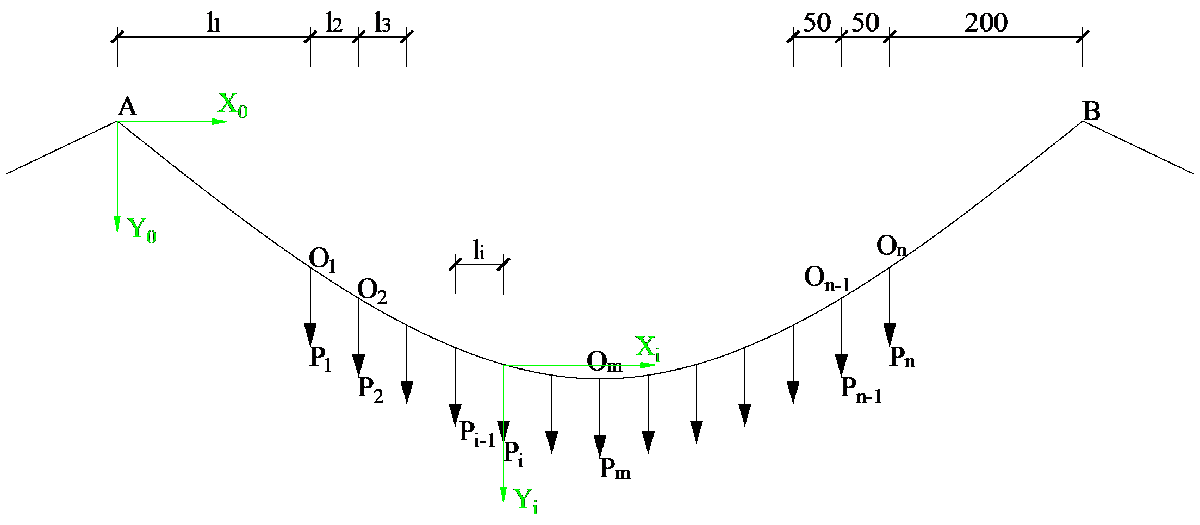

任意两端悬链线高差：


$$\Delta h_i =y_i \left(l_i \right)-y_i \left(0\right)=c\left\lbrack \cosh \left(\frac{l_i }{c}+a_i \right)-{\cosh \;a}_i \right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(3\right)$$


`在Iter_ai.mlx中的公式(2)可知，ai是a1和H的函数，即`


$$a_i =a_i \left({H,\;a}_1 \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(4\right)$$


把(4)式带入(3)式，每一段悬链线的高差$\Delta h_i$也是`a1和H的函数，即：`


$$\Delta h_i =\Delta h_i \left(H,{\;a}_1 \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(5\right)$$


将每一段悬链线的高差$\Delta h_i$求和，如果`a1和H都是正确的值，那么会有:`

- $\sum_{i=1}^{n+1} \Delta h_i =h_A -h_B$。其中$h_A$为$A$点的高程，$h_B$为$B$点的高程；

- $\sum_{i=1}^m \Delta h_i =h_A -h_{O_m }$。其中$h_A$为$A$点的高程，$h_{O_m }$为$O_m$点的高程。

但是`a1和H都是未知的待定值，求解2个未知量需要以下2个方程：`


$$f_1 \left(H,{\;a}_1 \right)=\sum_{i=1}^{n+1} \Delta h_i \left(H,{\;a}_1 \right)-\left(h_A -h_B \right)=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(6\right)$$



$$f_2 \left(H,{\;a}_1 \right)=\sum_{i=1}^m \Delta h_i \left(H,{\;a}_1 \right)-\left(h_A -h_{O_m } \right)=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(7\right)$$


同时求解方程(6)和方程(7)等价于最小化以下函数：


$$\min_{H,a_1 } f\left(H,{\;a}_1 \right)=\min_{H,a_1 } \left\lbrace {\left\lbrack f_1 \left(H,a_1 \right)\right\rbrack }^2 +{\left\lbrack f_2 \left(H,a_1 \right)\right\rbrack }^2 \right\rbrace \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(8\right)$$


### 2.2 参数初始化

初始化一些已知量

% 主缆自重相关
gamma_cable = 78.5; % 主缆容重，单位kN/m^3
D_cable = 1;  % 主缆截面直径，单位m
A_cable = pi/4*D_cable^2; % 主缆截面面积，单位m^2
q_cable = A_cable * gamma_cable; % 主缆自重集度q，单位kN/m

% 主梁相关
l_beam_seg = 12.5; % 吊杆之间的主梁长度，一段主梁的长度，单位m，常数
gamma_beam = 78.5; % 主梁容重，单位kN/m^3
A_beam = 1; % 主梁截面面积，单位m^2
q_beam = A_beam * gamma_beam; % 主梁自重集度q，单位kN/m

% 吊杆相关
n = 119;    % 吊杆数目n
Li = l_beam_seg * ones([1,n+1]);   % Li为每个悬链线分段的水平长度组成的向量，length(L) = n+1
P = q_beam * l_beam_seg * ones([1,n]);   % 吊杆拉力P，P中每个元素表示第i根吊杆的拉力P_i，length(P) = n


hA = 200;   % A点的高程
hB = 200;   % B点的高程
hOm = 50;  % 跨中O_m点的高程，也就是主缆垂度

当n是偶数的情况：令此时的垂度 = $h_A -h_{O_m }$=$h_A -h_{O_{m+1} }$

% 设m为跨中中点
if mod(n,2) == 1 % n是奇数的情况
    m = (n+1)/2;
elseif mod(n,2) == 0 % n是偶数的情况
    m = n/2;
end

将目标函数中需要的数据写一个.mat文件

save('InitData.mat','q_cable','q_beam','l_beam_seg','n','Li','P','hA','hB','hOm','m')

### 2.3 目标函数

## 3. 其他参数的设定

### 3.1 初始值设定

初始化 $x=\left\lbrack H,a_1 \right\rbrack$。

其中，水平力$H$的初始值通过抛物线确定，$a_1$初始值为0。

x0 = zeros([1,2]); % x的初始值向量
x0(1) = Init_H();

### 3.2 设置线性约束

没有非线性约束。

线性约束的表达式：


$$A\cdot x\le b$$


要只设置水平力$H>0$的约束，不设置$a_1$的约束，即：


$$\left\lbrack \begin{array}{cc}
-1 & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
H\\
a_1 
\end{array}\right\rbrack \le \left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$


A = [-1,0;0,0];
b = [0;0];

### 3.3 优化算法的选择

% options = optimoptions('fmincon','Display','iter','Algorithm','sqp');

## 4. 优化函数的调用

fun = @ObjectFun;
A;
b;
Aeq = [];
beq = [];
lb = [];
ub = [];
nonlcon = [];
x0;
[x,fval] = fmincon(fun,x0,A,b,Aeq,beq,lb,ub,nonlcon)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x = 	1.0e+05 *

    2.6430    0.0000


fval = 1.6067e-09

## 生成悬链线形状

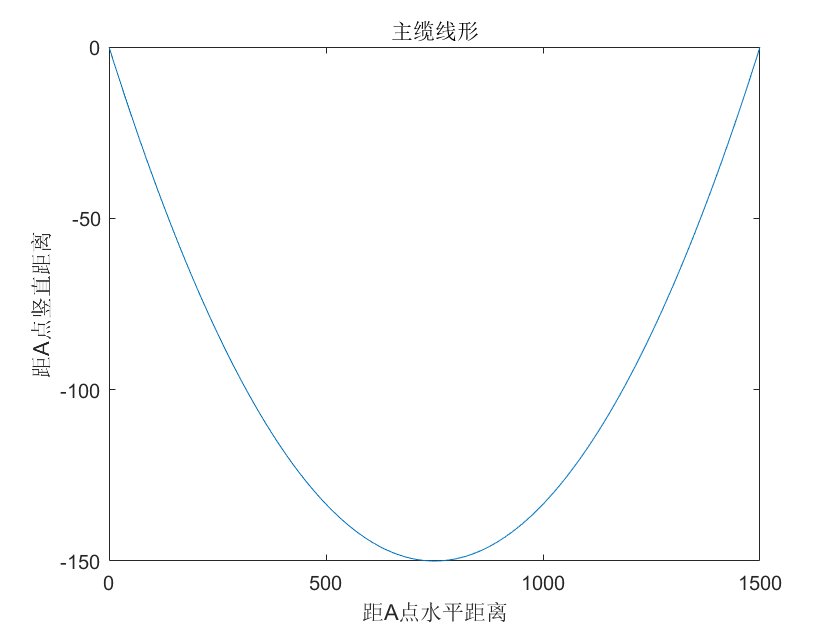

[Xi,Yi] = Seg_catenary(q_cable,n,Li,P,x);
X = zeros([1,length(Xi)+1]);
Y = zeros([1,length(Yi)+1]);

for i=2:length(X)
    X(i) = Xi(i-1) + X(i-1);
    Y(i) = Yi(i-1) + Y(i-1);
end

plot(X,-Y)
title('主缆线形')
xlabel('距A点水平距离')
ylabel('距A点竖直距离')